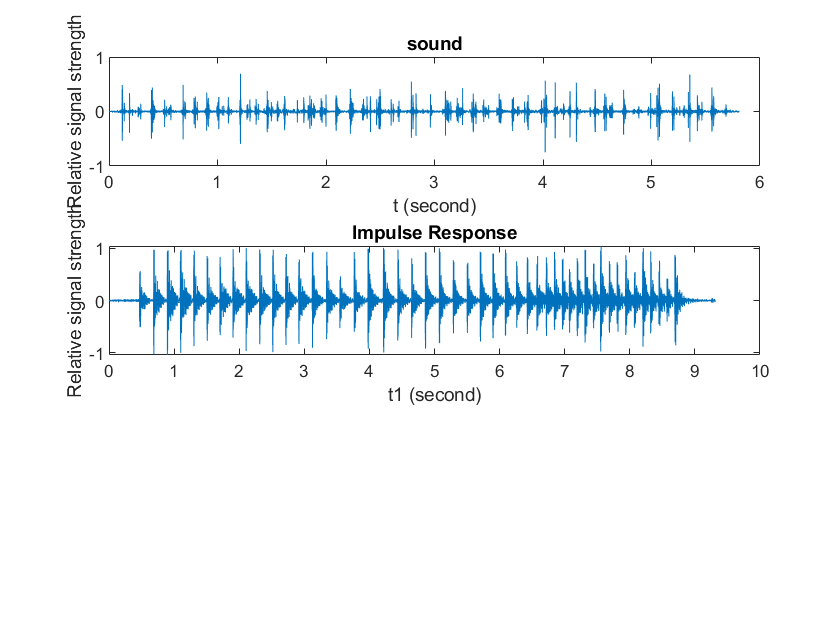

[sig1, fs] = audioread('N.wav'); % import the song
t = [1:length(sig1)]/fs; 
subplot(3,1,1)
plot(t, sig1) % plot the song
xlabel('t (second)')
ylabel('Relative signal strength')
title('sound')

p=audioplayer(sig1,fs);
play(p)

[sig2, fs] = audioread('M.wav'); % import the song
t1 = [1:length(sig2)]/fs; 
subplot(3, 1, 2) 
plot(t1, sig2) % plot the song
xlabel('t1 (second)')
ylabel('Relative signal strength')
title('Impulse Response')


p=audioplayer(sig2,fs);
play(p)

w = conv(sig1,sig2);
t2 = 0:1:10;
subplot(3,1,3);
plot(t2,w);
xlabel('t2 (second)')
ylabel('Relative signal strength')
title('Convolved Signal')
